clear all

load 'C:\SortingFolder\HIP\NormalizedIndexesTableMUA.mat';
load 'C:\SortingFolder\HIP\SignificanceWindowTableMUA.mat'; %The matrix obtained from the fuction ExtractMatFiles.m
load 'C:\SortingFolder\HIP\NormalizedIndexesTable.mat';
load 'C:\SortingFolder\HIP\SignificanceWindowTable.mat';
rangoY = [0 80]; % Y-axis range

Table_DG_A = load ('D:\Jazmin\MultichannelDataTanks\HIP\NormalizedIndexTable\DG Auditory\NormalizedIndexesTable_DG_A.mat');
Table_DG_S = load ('D:\Jazmin\MultichannelDataTanks\HIP\NormalizedIndexTable\DG SIG\NormalizedIndexesTable_DG_S.mat');
Table_CA1_A = load ('D:\Jazmin\MultichannelDataTanks\HIP\NormalizedIndexTable\CA1 Auditory\NormalizedIndexesTable_CA1_A.mat');
Table_CA1_S = load ('D:\Jazmin\MultichannelDataTanks\HIP\NormalizedIndexTable\CA1 SIG\NormalizedIndexesTable_CA1_S.mat');

SignificanceWindowTable = [SignificanceWindowTableMUA;SignificanceWindowTable];
NormalizedIndexesTable = [NormalizedIndexesTableMUA;NormalizedIndexesTable;Table_DG_A.NormalizedIndexesTable;Table_DG_S.NormalizedIndexesTable;Table_CA1_A.NormalizedIndexesTable;Table_CA1_S.NormalizedIndexesTable];

UN = load ('C:\Jazmin\HIP\spiketable_Aud_Sig.mat');
MUA = load ('C:\Jazmin\HIP\spiketable_Aud_Sig_MUA.mat');
UN.spiketable.unitloc = [];
SpiketableComplete = [UN.spiketable;MUA.spiketable];
DG_A = size(Table_DG_A.NormalizedIndexesTable,1);
DG_S = size(Table_DG_S.NormalizedIndexesTable,1);
CA1_A = size(Table_CA1_A.NormalizedIndexesTable,1);
CA1_S = size(Table_CA1_S.NormalizedIndexesTable,1);
s1 = size(SpiketableComplete,1);
SpiketableComplete.Auditory(s1:(s1+DG_A))=1;

SpiketableComplete.AuditoryP(s1:(s1+DG_A))=1;
SpiketableComplete.Significance(size(SpiketableComplete,1):(size(SpiketableComplete,1)+DG_S))=1;

s2 = size(SpiketableComplete,1);
SpiketableComplete.Auditory(s2:(s2+CA1_A))=1;

SpiketableComplete.AuditoryP(s2:(s2+CA1_A))=1;
SpiketableComplete.Significance(size(SpiketableComplete,1):(size(SpiketableComplete,1)+CA1_S))=1;


Auditory = sum(SpiketableComplete.Auditory)

Auditory = 186

SIG = sum(SpiketableComplete.Significance)

SIG = 45

% %Bootstrapping significance
% 
% Path = 'C:\SortingFolder\HIP\CSI_Boottstrap.xlsx';
% 
% % Import table
% HIP_Multi  = readtable(Path);
% HIParray = table2array(HIP_Multi(:,["CSI","Rango_1","Rango_2"]));
% % HIParray(any(isnan(HIParray), 2), :) = [];
% 
% n=0;
% m=0;
% for i = 1:size(HIParray,1)
%     if HIParray(i,2)<0 && HIParray(i,3)>0
%         n = n + 1;
%         NonSignificantAll(n,1) = i;
%     else
%         m = m + 1;
%         SignificantAll(m,1) = i;
%     end
% end

% Significance 
n= 1;
m= 1;
for i = 1: size(SpiketableComplete,1)
    if SpiketableComplete.Auditory(i) 
        % == 1 && SpiketableComplete.AuditoryP(i) == 1 
        SIscatterIndx(n,1)=i;
        n = n + 1;
    end

    if SpiketableComplete.Significance(i) == 1
        SignificantSSA(m,1) = i;
        m = m + 1;
    end
end



%SI
figure
%Create histogram
scatter(NormalizedIndexesTable.SI1(SIscatterIndx,1),NormalizedIndexesTable.SI2(SIscatterIndx,1),'filled', 'MarkerFaceColor','#990033', 'MarkerFaceAlpha',.25,'MarkerEdgeAlpha',.25);
hold on
scatter(NormalizedIndexesTable.SI1(SignificantSSA,1),NormalizedIndexesTable.SI2(SignificantSSA,1),'filled', 'MarkerFaceColor','#990033', 'MarkerFaceAlpha',1);
xlim([-1 1]);
ylim([-1 1]);
title('SI');
xlabel('SI F1');
ylabel('SI F2');
%Calculating the mean and error
SI_Mean = mean([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],"omitnan")

SI_Mean = 0.0362

SI_std = std([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],"omitnan");
err_SI = SI_std / sqrt((size([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],1))*2)

err_SI = 0.0116


SI_Mean_S = mean([NormalizedIndexesTable.SI1(SignificantSSA,1);NormalizedIndexesTable.SI2(SignificantSSA,1)],"omitnan")

SI_Mean_S = 0.1476

SI_std_S = std([NormalizedIndexesTable.SI1(SignificantSSA,1);NormalizedIndexesTable.SI2(SignificantSSA,1)],"omitnan");
err_SI_S = SI_std_S / sqrt((size([NormalizedIndexesTable.SI1(SignificantSSA,1);NormalizedIndexesTable.SI2(SignificantSSA,1)],1))*2)

err_SI_S = 0.0243


[h p_SI] = ttest([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)]) 

h = 1

p_SI = 0.0335

[h p_SI_sig] = ttest([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)]) 

h = 1

p_SI_sig = 0.0335

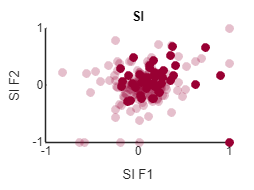


%Save figure
cd 'C:\Jazmin\HIP\SI'
saveas(gcf,'SI_ALL.pdf');
saveas(gcf,'SI_ALL.tif');
saveas(gcf,'SI_ALL.fig');
hold off

[h_kstest_SI,p_kstest_SI] = kstest([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)])

h_kstest_SI = logical
   1


p_kstest_SI = 4.0744e-29

[h_kstest_SI_S,p_kstest_SI_S] = kstest([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)])

h_kstest_SI_S = logical
   1


p_kstest_SI_S = 4.0744e-29

[h_ad_SI,p_ad_SI] = adtest([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)])

h_ad_SI = logical
   1


p_ad_SI = 5.0000e-04

[h_ad_SI_S,p_ad_SI_S] = adtest([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)])

h_ad_SI_S = logical
   1


p_ad_SI_S = 5.0000e-04

% % Significance SI Histogram
% n= 1;
% m= 1;
% for i = 1: size(SignificanceWindowTable,1)
%     if SignificanceWindowTable.SignificanceDEV1(i,1) > 0
%         SI1HistIndx(n,1)=i;
%         n = n + 1;
%     end
%     if SignificanceWindowTable.SignificanceDEV2(i,1) > 0
%         SI2HistIndx(m,1)=i;
%         m = m + 1;
%     end 
%  end

% % SI
% figure
% %Create histogram
% histogram([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',.25,'EdgeAlpha',.25);
% xlim([-1 1]);
% ylim([0 150]);
% xline(0,'LineWidth',2);
% title('SI');
% xlabel('SI index');
% ylabel('repetitions');
% 
% %Calculating the mean and error
% SI_Mean = mean([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],"omitnan")
% SI_std = std([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],"omitnan");
% err_SI = SI_std / sqrt((size([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],1))*2)
% xline(SI_Mean,'LineWidth',2.5);
% 
% %Save figure
% cd 'C:\Jazmin\HIP\SI';
% saveas(gcf,'SI_HIST_ALL.pdf');
% saveas(gcf,'SI_HIST_ALL.tif');
% saveas(gcf,'SI_HIST_ALL.fig');

% CSI SignificantSSA
figure
%Create histogram
histogram(NormalizedIndexesTable.CSI(SIscatterIndx,1),'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
histogram(NormalizedIndexesTable.CSI(SignificantSSA,1),'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim(rangoY);
xline(0,'LineWidth',2);
title('CSI');
xlabel('CSI index');
ylabel('repetitions');

%Calculating the mean and error
CSI_Mean = mean(NormalizedIndexesTable.CSI(SIscatterIndx,1),"omitnan")

CSI_Mean = 0.0588

CSI_std = std(NormalizedIndexesTable.CSI(SIscatterIndx,1),"omitnan");
err_CSI = CSI_std / sqrt(size(NormalizedIndexesTable.CSI(SIscatterIndx,1),1))

err_CSI = 0.0172

xline(CSI_Mean,'LineWidth',2);

CSI_Mean_S = mean(NormalizedIndexesTable.CSI(SignificantSSA,1),"omitnan")

CSI_Mean_S = 0.1825

CSI_std_S = std(NormalizedIndexesTable.CSI(SignificantSSA,1),"omitnan");
err_CSI_S = CSI_std_S / sqrt(size(NormalizedIndexesTable.CSI(SignificantSSA,1),1))

err_CSI_S = 0.0334

xline(CSI_Mean_S,'LineWidth',2.5);


[h p_CSI] = ttest(NormalizedIndexesTable.CSI(SIscatterIndx,1)) 

h = 1

p_CSI = 0.0012

[h p_CSI_sig] = ttest(NormalizedIndexesTable.CSI(SignificantSSA,1)) 

h = 1

p_CSI_sig = 2.0852e-06

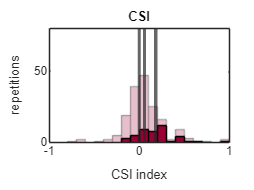


% [p_CSI h] = signrank(NormalizedIndexesTable.CSI(SIscatterIndx,1)) 
% [p_CSI_sig h] = signrank(NormalizedIndexesTable.CSI(SignificantSSA,1)) 

%Save figure
cd 'C:\Jazmin\HIP\CSI';
saveas(gcf,'CSI_ALL.pdf');
saveas(gcf,'CSI_ALL.tif');
saveas(gcf,'CSI_ALL.fig');
hold off


[h_kstest_CSI,p_kstest_CSI] = kstest(NormalizedIndexesTable.CSI(SIscatterIndx,1))

h_kstest_CSI = logical
   1


p_kstest_CSI = 9.4535e-21

[h_kstest_CSI_S,p_kstest_CSI_S] = kstest(NormalizedIndexesTable.CSI(SignificantSSA,1))

h_kstest_CSI_S = logical
   1


p_kstest_CSI_S = 7.2191e-08

[h_ad_CSI,p_ad_CSI] = adtest(NormalizedIndexesTable.CSI(SIscatterIndx,1))

h_ad_CSI = logical
   1


p_ad_CSI = 5.0000e-04

[h_ad_CSI_S,p_ad_CSI_S] = adtest(NormalizedIndexesTable.CSI(SignificantSSA,1))

h_ad_CSI_S = logical
   1


p_ad_CSI_S = 0.0221

% iMM
iMMcasc = cat(1,NormalizedIndexesTable.iMM1ca(SIscatterIndx,1),NormalizedIndexesTable.iMM2cd(SIscatterIndx,1));
figure
hold on
iMMcasc_S = cat(1,NormalizedIndexesTable.iMM1ca(SignificantSSA,1),NormalizedIndexesTable.iMM2cd(SignificantSSA,1));
%Create histogram
histogram(iMMcasc,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',.25,'EdgeAlpha',.25);
histogram(iMMcasc_S,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iMM');
xlabel('iMM index');
ylabel('repetitions');

%Calculating the mean and error
iMMcasc_Mean = nanmean(iMMcasc)

iMMcasc_Mean = 0.0521

iMMcasc_std = nanstd(iMMcasc);
err_iMMcasc = iMMcasc_std / sqrt(size(iMMcasc,1))

err_iMMcasc = 0.0154

xline(iMMcasc_Mean,'LineWidth',2);

iMMcasc_Mean_S = nanmean(iMMcasc_S)

iMMcasc_Mean_S = 0.1544

iMMcasc_std_S = nanstd(iMMcasc_S);
err_iMMcasc_S = iMMcasc_std_S / sqrt(size(iMMcasc_S,1))

err_iMMcasc_S = 0.0325

xline(iMMcasc_Mean_S,'LineWidth',2.5);

[h p_iMM] = ttest(iMMcasc)

h = 1

p_iMM = 0.0015

[h p_iMM_sig ] = ttest(iMMcasc_S)

h = 1

p_iMM_sig = 7.6444e-06

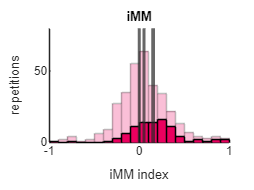


% [p_iMM_sig h] = signrank(iMMcasc)
% [p_iMM_sig h] = signrank(iMMcasc_sig)

%Save figure
PathiMM = 'C:\Jazmin\HIP\iMM';
cd (PathiMM);
saveas(gcf,'iMM_ALL.pdf');
saveas(gcf,'iMM_ALL.tif');
saveas(gcf,'iMM_ALL.fig');
hold off

[h_kstest_iMM,p_kstest_iMM] = kstest(iMMcasc)

h_kstest_iMM = logical
   1


p_kstest_iMM = 8.3616e-29

[h_kstest_iMM_S,p_kstest_iMM_S] = kstest(iMMcasc_S)

h_kstest_iMM_S = logical
   1


p_kstest_iMM_S = 9.3830e-11

[h_ad_iMM,p_ad_iMM] = adtest(iMMcasc)

h_ad_iMM = logical
   1


p_ad_iMM = 5.0000e-04

[h_ad_iMM_S,p_ad_iMM_S] = adtest(iMMcasc_S)

h_ad_iMM_S = logical
   1


p_ad_iMM_S = 0.0029

% iPE CA1 SignificantSSA
iPEcasc = cat(1,NormalizedIndexesTable.iPE1ca(SIscatterIndx,1),NormalizedIndexesTable.iPE2cd(SIscatterIndx,1));
iPEcasc_S = cat(1,NormalizedIndexesTable.iPE1ca(SignificantSSA,1),NormalizedIndexesTable.iPE2cd(SignificantSSA,1));
figure
%Create histogram
histogram(iPEcasc,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
histogram(iPEcasc_S,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iPE');
xlabel('iPE index');
ylabel('repetitions');

%Calculating the mean and error
iPEcasc_Mean = nanmean(iPEcasc)

iPEcasc_Mean = 0.0885

iPEcasc_std = nanstd(iPEcasc);
err_iPEcasc = iPEcasc_std / sqrt(size(iPEcasc,1))

err_iPEcasc = 0.0182

xline(iPEcasc_Mean,'LineWidth',2);

iPEcasc_Mean_S = nanmean(iPEcasc_S)

iPEcasc_Mean_S = 0.0912

iPEcasc_std_S = nanstd(iPEcasc_S);
err_iPEcasc_S = iPEcasc_std_S / sqrt(size(iPEcasc_S,1))

err_iPEcasc_S = 0.0369

xline(iPEcasc_Mean_S,'LineWidth',2.5);

[h p_iPE] = ttest(iPEcasc)

h = 1

p_iPE = 5.7921e-06

[h p_iPE_sig] = ttest(iPEcasc_S)

h = 1

p_iPE_sig = 0.0154

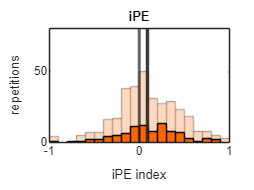


% [p_iPE h] = signrank(iPEcasc)
% [p_iPE_sig h] = signrank(iPEcasc_sig)
%Save figure
cd 'C:\Jazmin\HIP\iPE';
saveas(gcf,'iPE_ALL.pdf');
saveas(gcf,'iPE_ALL.tif');
saveas(gcf,'iPE_ALL.fig');
hold off

[h_kstest_iPE,p_kstest_iPE] = kstest(iPEcasc)

h_kstest_iPE = logical
   1


p_kstest_iPE = 1.7138e-23

[h_kstest_iPE_S,p_kstest_iPE_S] = kstest(iPEcasc_S)

h_kstest_iPE_S = logical
   1


p_kstest_iPE_S = 8.2234e-07

[h_ad_iPE,p_ad_iPE] = adtest(iPEcasc)

h_ad_iPE = logical
   0


p_ad_iPE = 0.0965

[h_ad_iPE_S,p_ad_iPE_S] = adtest(iPEcasc_S)

h_ad_iPE_S = logical
   0


p_ad_iPE_S = 0.5480

% iRS CA1
iRScasc = cat(1,NormalizedIndexesTable.iRS1ca(SIscatterIndx,1),NormalizedIndexesTable.iRS2cd(SIscatterIndx,1));
iRScasc_S = cat(1,NormalizedIndexesTable.iRS1ca(SignificantSSA,1),NormalizedIndexesTable.iRS2cd(SignificantSSA,1));
figure
%Create histogram
histogram(iRScasc,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',.25,'EdgeAlpha',.25);
hold on
histogram(iRScasc_S,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',1,'EdgeAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iRS');
xlabel('iRS index');
ylabel('repetitions');

%Calculating the mean and error
iRScasc_Mean = nanmean(iRScasc)

iRScasc_Mean = -0.0364

iRScasc_std = nanstd(iRScasc);
err_iRScasc = iRScasc_std / sqrt(size(iRScasc,1))

err_iRScasc = 0.0158

xline(iRScasc_Mean,'LineWidth',2.5);

iRScasc_Mean_S = nanmean(iRScasc_S)

iRScasc_Mean_S = 0.0632

iRScasc_std_S = nanstd(iRScasc_S);
err_iRScasc_S = iRScasc_std_S / sqrt(size(iRScasc_S,1))

err_iRScasc_S = 0.0338

xline(iRScasc_Mean_S,'LineWidth',2.5);

[h p_iRS] = ttest(iRScasc)

h = 1

p_iRS = 0.0297

[h p_iRS_sig] = ttest(iRScasc_S)

h = 0

p_iRS_sig = 0.0649

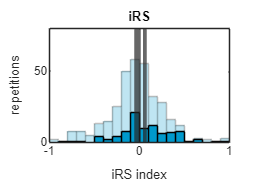


% [p_iRS_sig h] = signrank(iRScasc)
% [p_iRS h] = signrank(iRScasc_S)

%Save figure
cd 'C:\Jazmin\HIP\iRS';
saveas(gcf,'iRS_ALL.pdf');
saveas(gcf,'iRS_ALL.tif');
saveas(gcf,'iRS_ALL.fig');
hold off

[h_kstest_iRS,p_kstest_iRS] = kstest(iRScasc)

h_kstest_iRS = logical
   1


p_kstest_iRS = 1.4649e-25

[h_kstest_iRS_S,p_kstest_iRS_S] = kstest(iRScasc_S)

h_kstest_iRS_S = logical
   1


p_kstest_iRS_S = 4.1527e-07

[h_ad_iRS,p_ad_iRS] = adtest(iRScasc)

h_ad_iRS = logical
   1


p_ad_iRS = 5.0000e-04

[h_ad_iRS_S,p_ad_iRS_S] = adtest(iRScasc_S)

h_ad_iRS_S = logical
   0


p_ad_iRS_S = 0.0667

% NormalizedIndexes = table(CSI,SI1, iMM1ca, iRS1ca, iPE1ca,SI2, iMM2cd, iRS2cd, iPE2cd, NormDEVca1, NormSTDca1, NormCTRca1, NormDEVcd2, NormSTDcd2, NormCTRcd2, DEV1, STD1, CTRCA1, DEV2, STD2, CTRCD2);